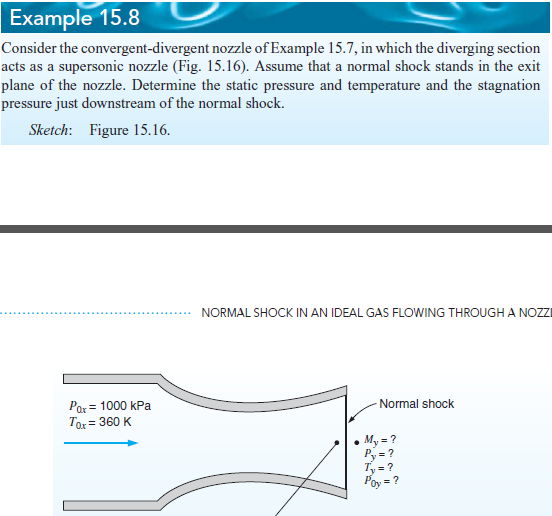

# given

u = symunit;
Ae = 1000*u.mm^2;
At = 500*u.mm^2;
pox = 1000*u.kPa;
Tox = 360*u.K;
Toy = 360*u.K;
air = ig;

# mach numbers at the shock

syms Mx;
f = matlabFunction(Ae/At-air.A_As(Mx));
Mx = fzero(f, [1 12]);
My = air.My(Mx);

# downstream shock properties

poy = pox*air.poy_pox(Mx);
poy_vpa = vpa(poy, 5)

$$poy\_vpa = 629.41\,\mathrm{kPa}$$

py = poy*air.p_po(My);
py_vpa = vpa(py, 5)

$$py\_vpa = 513.4\,\mathrm{kPa}$$

Ty = Toy*air.T_To(My);
Ty_vpa = vpa(Ty, 5)

$$Ty\_vpa = 339.64\,K$$